# **数学实验二**

#### 1. 用给定的多项式$y=x^{3}-6x^{2}+5x-3$，产生一组数据(xi,yi),i=1~n。再在yi上添加服从正态分布N（0,1）的随机干扰，得到干扰数据zi。用(xi,zi)作m=3次多项式拟合，与原系数进行比较。如果正态分布的参数$\mu , \sigma^{2}$及拟合多项式阶数m允许变化，结果如何？（对于 m的变化，只讨论取2或4两种情况）

#### 解：

- 设置正态分布的均值和方差，设置拟合多项式阶数m：

mu=0.4;%默认取0
sigma=5;%默认取1
m=3;%默认取3

- 设置生成数据个数n、数据的范围：

n = 24;%默认取20
minx=-3;%下限，默认取-5
maxx=7;%上限，默认取5

- 生成数据并添加干扰：

% 给定多项式的系数
C = [1, -6, 5,-3]; % 多项式为 x^3 - 6x^2 + 5x - 3
% 生成均匀分布的x值
x1 = linspace(minx, maxx, n);
% 计算对应的y值
y1 = polyval(C, x1);
% 生成标准正态分布的随机数
standard_normal = randn(1, n);
% 根据线性变换得到具有指定均值和方差的随机数
z = mu + sigma * standard_normal;
% 添加干扰
z = y1 + z;

- 进行拟合并比较系数：

% 用m=3次多项式拟合数据
p = polyfit(x1, z, m);
% 比较原始系数与拟合系数
fprintf('原始系数: %s\n', mat2str(C));

原始系数: [1 -6 5 -3]


fprintf('拟合系数: %s\n', mat2str(p));

拟合系数: [1.0016682714034 -6.2184620127918 5.25932852914422 0.871474946088373]


- 绘制原始数据和拟合曲线

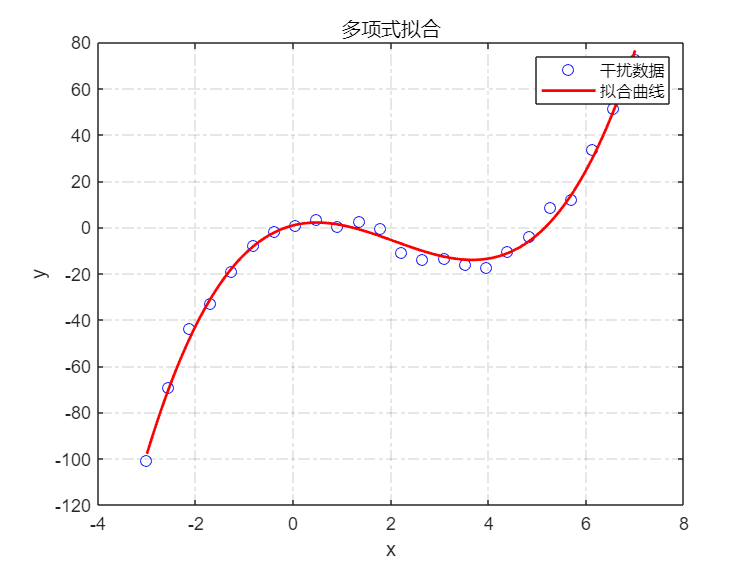

% 绘制图像
xx = linspace(min(x1), max(x1), n*5);
yy = polyval(p, xx);
P=plot(x1, z, 'bo', xx, yy, 'r-');
% 设置线宽
P(2).LineWidth =1.5;
% 打开网格
grid on;
set(gca, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '-.');
% 设置图例、坐标轴和标题
legend('干扰数据', '拟合曲线');
xlabel('x');
ylabel('y');
title('多项式拟合');

- 通过滑动滑块，可见改变正态分布的均值和方差会对原始数据的分布有影响，但拟合效果相差不大。

              而改变拟合阶数m会对拟合效果有较大影响，总体来看阶数越高，拟合效果越精准。

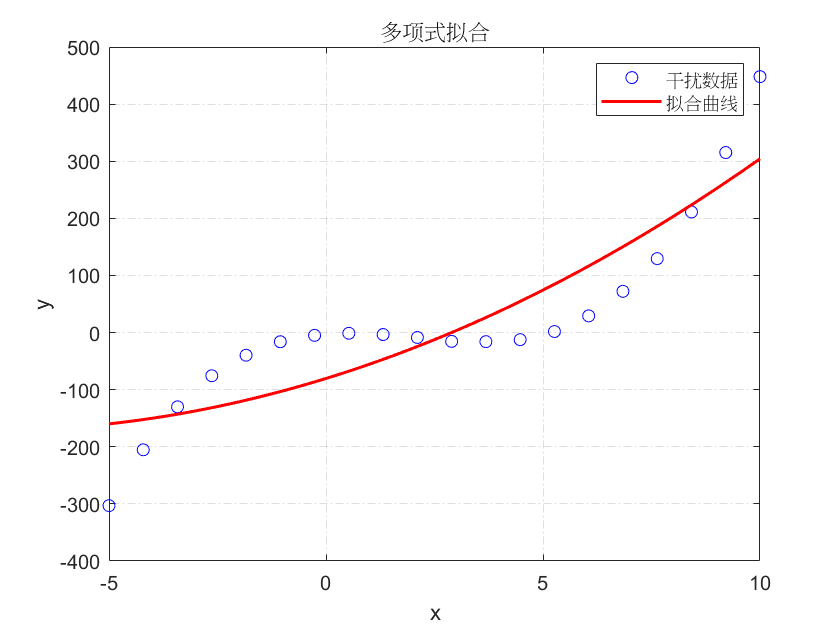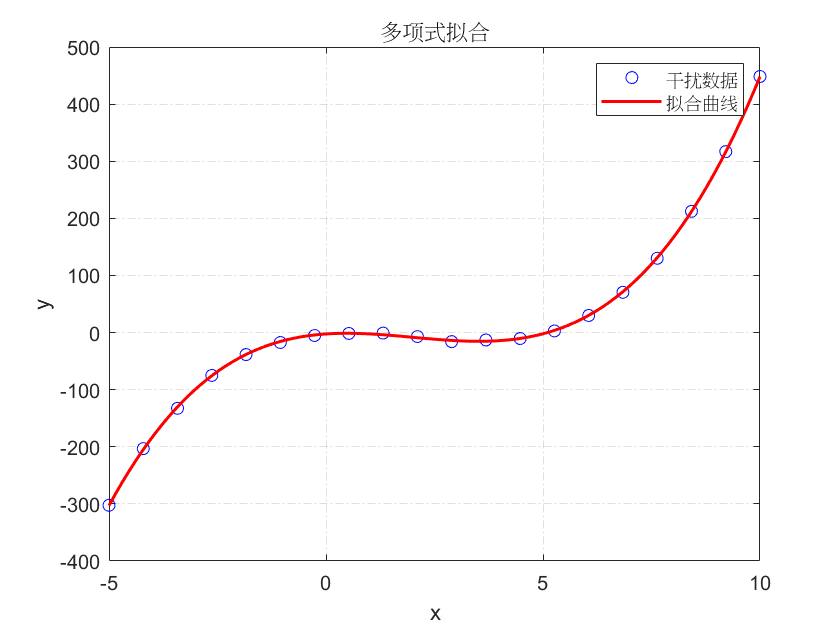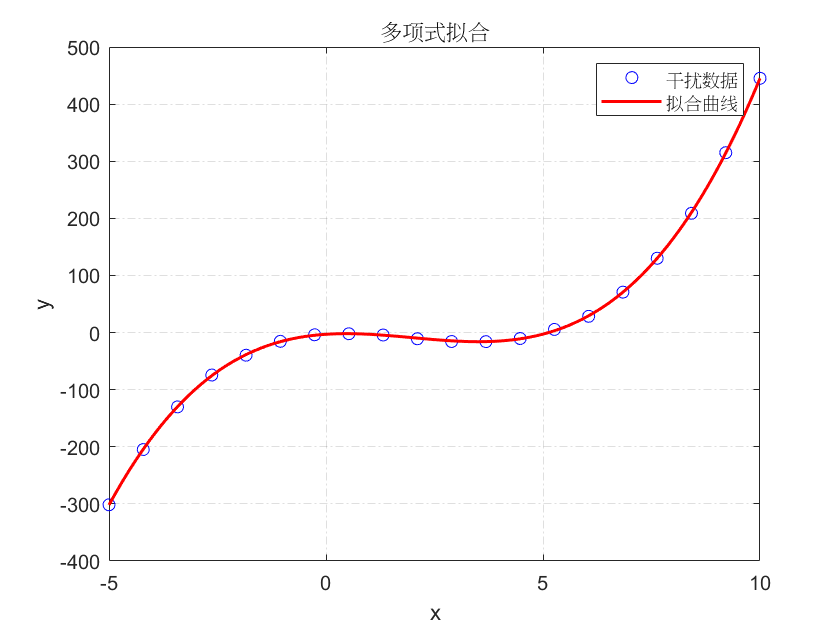

                以上从左至右分别为m=2，3，4时的拟合图象

#### 2. 地图问题    对一个欧洲国家的地图（比例尺为 4.5：10000000）边境线进行采样，以由西向东方向为x轴，由南到北方向为y轴，并将从最西边界点到最东边界点在2轴上的区间适当地划分为若干段，在每个分点的？方向测出南边界点和北边界点的y坐标y1和y2，这样就得到了附件表格中的数据（单位：mm）。请估算出它的国土面积和边境线长度，根据你的计算结果确定这是哪个国家，绘制该国边境线，并给出你的面积计算相对误差。

#### 解：

- 读取表格数据：

clear;
% 读取数据
data = xlsread('实验2附件.xlsx', '地图边界点采样数据');
x1 = data(:, 1);
y1 = data(:, 2);%北边界
y2 = data(:, 3);%南边界
L = size(x1);
length=L(1,1);%长度

- 通过多项式拟合得到拟合边界：

% 拟合边界线
n1=15;
n2=15;
% 经过滑块调整，发现拟合阶数均取15时拟合效果良好
P1 = polyfit(x1, y1, n1);

P2 = polyfit(x1, y2, n2);

- 计算国土面积和边境线长度：

% 计算总面积
f = @(x) polyval(P2, x) - polyval(P1, x);
total_area = integral(f, min(x1), max(x1)) * (10/ 4.5)^2; % 单位：平方千米
% 使用积分估计边界线长度
y1_fit = polyval(P1, x1);
y2_fit = polyval(P2, x1);
ddx = diff(x1); % 计算x轴上的差分
ddy1 = diff(y1_fit); % 计算南边界y轴上的差分
ddy2 = diff(y2_fit); % 计算北边界y轴上的差分
border_length = sum(sqrt(ddx.^2 + ddy1.^2)) + sum(sqrt(ddx.^2 + ddy2.^2));
border_length = border_length * (10/ 4.5);% 计算边界线长度
%  输出
fprintf('估算的国土面积为：%.2f 平方千米\n', total_area);

估算的国土面积为：41319.75 平方千米


fprintf('估算的边界线长度为：%.2f 千米\n', border_length);

估算的边界线长度为：990.49 千米


- 绘制边界线：

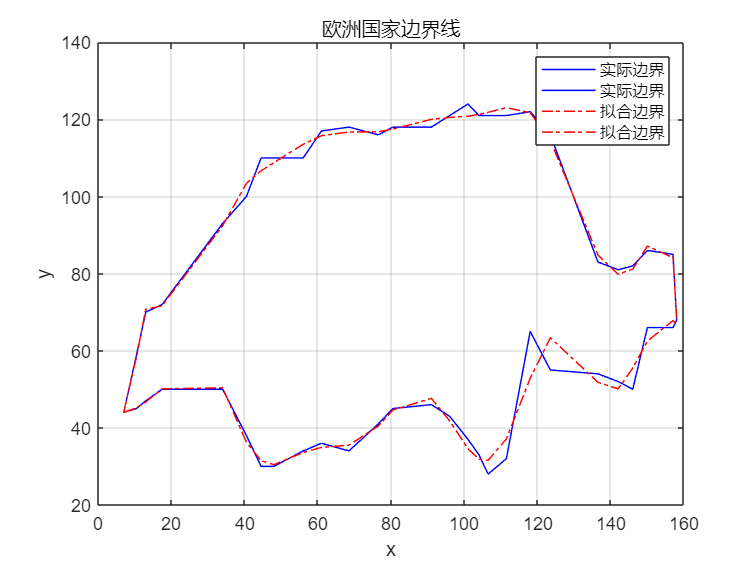

figure;
fig1=plot(x1,y1,'-b',x1,y2,'-b');
hold on;
fig2=plot(x1, y1_fit, '-.r', x1, y2_fit, '-.r');
% 设置线宽
fig1(1).LineWidth=0.8;fig1(2).LineWidth=0.8;
fig2(1).LineWidth=0.8;fig2(2).LineWidth=0.8;
% 设置图例、坐标轴和标题
xlabel('x');
ylabel('y');
title('欧洲国家边界线');
legend('实际边界', '实际边界','拟合边界', '拟合边界');
grid on;

- 由观察边界图和国土面积可知该国家为瑞士，其国土面积为41285平方千米。下面计算面积相对误差：

% 计算并输出误差
real_area=41285;
e=abs((total_area-real_area)/real_area);
fprintf("面积相对误差为%.6f",e*100);disp('%');

面积相对误差为0.084183%


#### 3. 编写程序，实现通用的分段 Lagrange 插值。输入参数：x，y（样本数据），xi（待计算点），阶数n（例如分段二次插值，则n=2）。返回值：yi（待插值点处计算值）。

#### 解：        

- 1）测试阶数从1到4，函数f1的插值效果：

clear;
% 初始化插值区间和样本点
x1=0:0.5:5;
x1_i=2.2;
y1=f1(x1);
n=4;
% 计算理论值和初始化
y1_i=f1(x1_i);
L1=zeros(1,n);
e1=zeros(1,n);
% 改变阶数，进行插值
for j=1:4
    L1(j)=Lagrange(x1,y1,x1_i,j);%调用通用分段Lagrange插值函数
    e1(j)=abs((L1(j)-y1_i)/y1_i);
end

- 输出结果：

disp("对于函数f1");

对于函数f1


disp("理论值为：");

理论值为：


disp(y1_i);

    0.6650



disp("阶数为1，2，3，4的拉格朗日插值拟合值分别为：")

阶数为1，2，3，4的拉格朗日插值拟合值分别为：


disp(L1);

    0.6525    0.6719    0.6670    0.6620



disp("阶数为1，2，3，4的拉格朗日插值相对误差分别为：")

阶数为1，2，3，4的拉格朗日插值相对误差分别为：


disp(e1);

    0.0188    0.0104    0.0030    0.0046



- 比较图形：

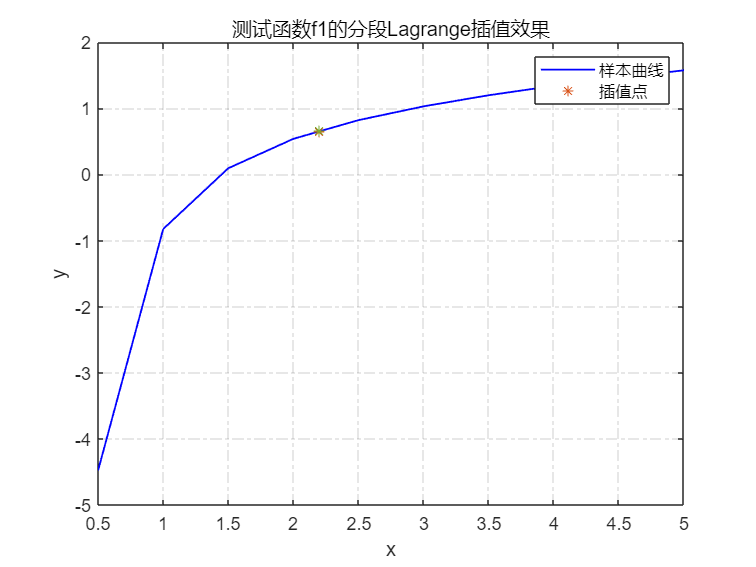

figure;
P=plot(x1,y1,'-b',x1_i,L1,'*');
% 打开网格
grid on;
set(gca, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '-.');
% 设置线宽
P(1).LineWidth=1.0;
% 设置图例、坐标轴和标题
legend('样本曲线', '插值点');
xlabel('x');
ylabel('y');
title('测试函数f1的分段Lagrange插值效果');

- 2）测试阶数从1到4，函数f1的插值效果：

% 初始化插值区间和样本点
x2=0:1:10;
x2_i=8.5;
y2=f2(x2);
n=4;
% 计算理论值和初始化
y2_i=f2(x2_i);
L2=zeros(1,n);
e2=zeros(1,n);
% 改变阶数，进行插值
for j=1:n
    L2(j)=Lagrange(x2,y2,x2_i,j);%调用通用分段Lagrange插值函数
    e2(j)=abs((L2(j)-y2_i)/y2_i);
end

- 输出结果：

disp("对于函数f2");

对于函数f2


disp("理论值为：");

理论值为：


disp(y2_i);

   1.2591e+04



disp("阶数为1，2，3，4的拉格朗日插值拟合值分别为：")

阶数为1，2，3，4的拉格朗日插值拟合值分别为：


disp(L2);

   1.0e+04 *

    1.2590    1.2591    1.2591    1.2591



disp("阶数为1，2，3，4的拉格朗日插值相对误差分别为：")

阶数为1，2，3，4的拉格朗日插值相对误差分别为：


disp(e2);

   1.0e-04 *

    0.9770    0.0103    0.0008    0.0001



- 比较图形：

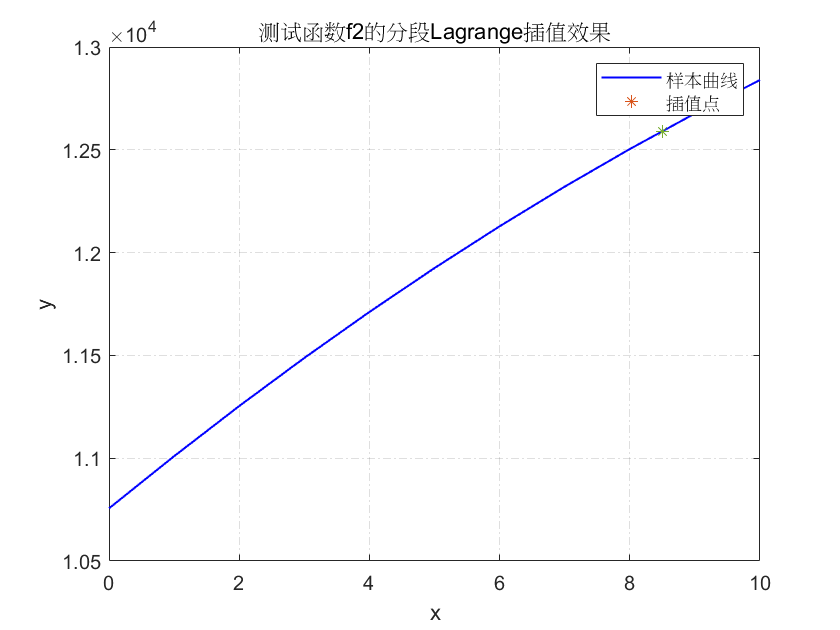

figure;
P=plot(x2,y2,'-b',x2_i,L2,'*');
% 打开网格
grid on;
set(gca, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '-.');
% 设置线宽
P(1).LineWidth=1.0;
% 设置图例、坐标轴和标题
legend('样本曲线', '插值点');
xlabel('x');
ylabel('y');
title('测试函数f2的分段Lagrange插值效果');

### 附录：

- 测试函数f1

function y=f1(x)%输入为行向量，输出为行向量
    l=length(x);
    y=zeros(1,l);
    for i=1:l
        y(i)=log(x(i))+1/(exp(x(i))+3)-1/(x(i)*x(i));
    end
end

- 测试函数f2

function y=f2(t)%Logistic模型的函数解
    b=[1.5037e4,0.0844];
    y= b(1)./(1+(exp(-b(2).*t).*(b(1)./10756-1)));
end

- 通用的Lagrange插值函数

function yi = Lagrange(X, Y, Xi, n)
% 参数： X为样本数据横坐标，
%       Y为样本数据纵坐标，
%       xi为需要插值的点的横坐标，
%       n为插值阶数
% 确保x和y是行向量
X = X(:)';
Y = Y(:)';
yi = zeros(size(Xi));
LENGTH = length(Xi);
% 对插值点进行计算
for k = 1: LENGTH
    L = zeros(1, n+1);
    [~, idx] = sort(abs(X - Xi(k)));
    x_near = idx(1:n+1);% 找到插值点Xi(k)附近的n+1个点
    for i = 1:n+1
        li = 1;        % 计算第i个Lagrange基多项式在Xi(k)处的值
        for j = 1:n+1
            if i ~= j 
                li = li * (Xi(k) - X(x_near(j))) / (X(x_near(i)) - X(x_near(j)));%构造L（i）的表达式
            end
        end
        L(i) = li;
    end
    yi(k) = sum(Y(x_near) .* L);% 计算得到插值结果
end
end